# Modelo SEIRS

**Universidad eafit**

**Primer Semestre 2024**

**Sistemas lineales**

**Carlos M. Veléz S.**

**Luis M. Martinez G.**

**Sebastian A. Amaya C.**

## 1. El Modelo SIERS

El modelo SEIRS, una piedra angular de la epidemiología, divide las poblaciones en compartimentos susceptibles (S), expuestos (E), infecciosas (I), recuperadas (R) y nuevamente susceptibles (S), lo que proporciona un enfoque estructurado para estudiar la dinámica de transmisión de enfermedades. A través de ecuaciones diferenciales, rastrea el movimiento de los individuos entre estos compartimentos a lo largo del tiempo, lo que refleja las transiciones de la susceptibilidad a la exposición, la infección y, en última instancia, la recuperación o la susceptibilidad nuevamente.

La versatilidad de este modelo se extiende a diversas aplicaciones, incluida la predicción de la propagación de enfermedades, la evaluación de estrategias de intervención y la optimización de la asignación de recursos durante los brotes. Al simular diferentes escenarios, los investigadores y los responsables de la formulación de políticas pueden anticipar la trayectoria de las enfermedades infecciosas, evaluar la eficacia de las medidas de control y tomar decisiones informadas para mitigar su impacto en la salud pública.

Su marco matemático proporciona información sobre las tasas de transmisión, los períodos de latencia y la dinámica de la inmunidad, lo que permite a las partes interesadas implementar medidas proactivas y gestionar eficazmente los brotes de enfermedades dentro de las poblaciones.

### **1.1. Descripción del modelo**

La mayoría de las descripciones matemáticas de la dinámica poblacional de las enfermedades infecciosas se basan en la capacidad de dividir la población en compartimentos discretos que no se superponen para así estudiar el flujo de los individuos a través de las diferentes clasificaciones. Para este Modelo se estudian 4 compartimientos:

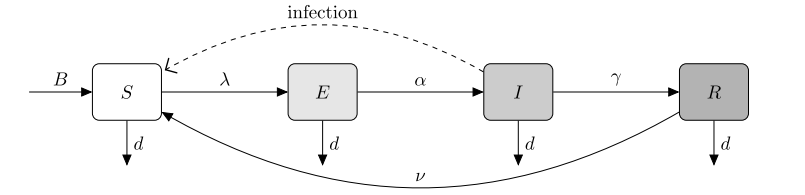

#### **Figura 1**

La figura 1 nos brinda un "esquema" del modelo y de la interacción de entre las poblaciones del modelo de esta práctica, es importante hacer clara ciertas consideraciones del modelo, primero, tomando una visión centrada en el patógeno, categorizamos al huésped (persona) por su estado con respecto al patógeno, Como las siglas del modelo indican los compartimientos en los que se divide la población son:

- Susceptibles(S):Individuos que no han sido infectados por la enfermedad y que pueden contraerla si entran en contacto con personas infectadas

- Infecciosas(I):Individuos actualmente infectados con la enfermedad y que pueden transmitirla a otros susceptibles.

- Recuperados(R):Individuos que han sido infectados previamente, pero ya se han recuperado de la enfermedad. Son inmunes y pueden volver a contraer la enfermedad.

- Expuestos(E): Individuos que han sido infectados con una enfermedad, pero que aún no son contagiosos.

- Población total (N): es la suma de todas las poblaciones anteriores

Además, podemos observar que se considera una población aislada y que la enfermedad modelada no es mortal, es decir la única entrada de nuevos integrantes es mediante nacimientos  y la única salida es mediante muerte por causas ajenas al patógeno, en la siguiente sección se explicara con mayor detalle la dinámica del modelo.

### **1.2. VARIABLES Y PARÁMETROS DEL MODELO**

Se puede observar que se usan varios parámetros para regular el flujo entre las diferentes poblaciones, a continuación se da una descripción de estas:

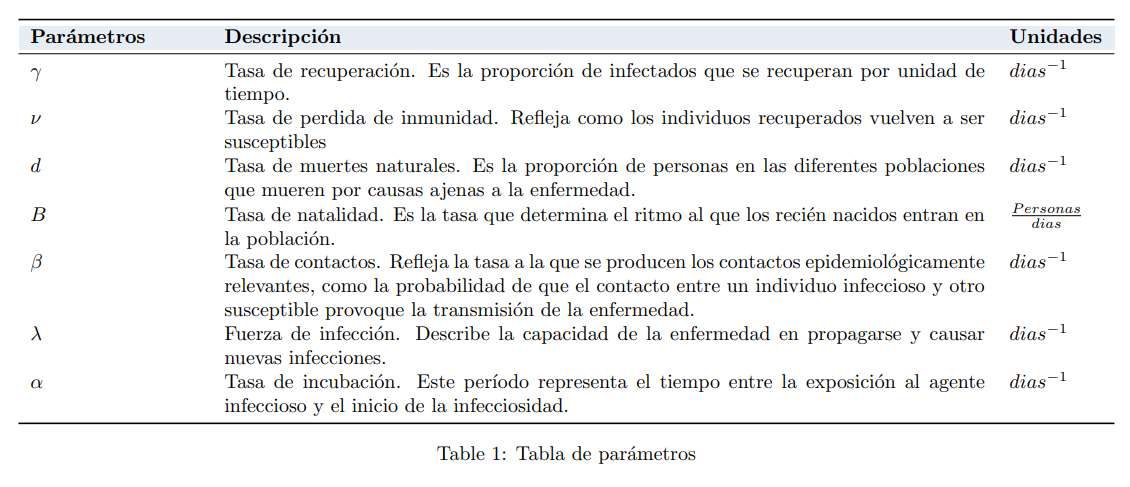

#### **Figura 2**

### **1.3 Ecuaciones del modelo**

Considerando la clasificación de la población previamente establecida, las ecuaciones no lineales del modelo se pueden describir de la siguiente manera:

La población susceptible `(S)` varía con el tiempo `(t)`, aumentando con la llegada de recién nacidos `(B) `y los recuperados que pierden su inmunidad `(νR)`, y disminuyendo con los susceptibles que son infectados `(-λS)` y los que han muerto por causas naturales `(-dS)`.


$$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$$
  

La población expuesta `(E)` varía con el tiempo `(t)`, incrementando con los susceptibles que han sido infectados `(λS)` y disminuyendo con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(-αE)` y los expuestos que han fallecido por causas naturales `(-dE)`.


$$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$$
  

La población infectada `(I)` varía con el tiempo `(t)`, aumentando con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(αE)`, y reduciendo con aquellos infectados que se han recuperado `(-γI) `o han fallecido por causas naturales `(-dI)`.


$$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$$
 

La población recuperada `(R)` varía con el tiempo `(t)`, incrementando con los individuos infectados que se han recuperado `(γI)` y reduciendo con aquellos recuperados que pierden su inmunidad y se vuelven susceptibles de nuevo `(-νR)` y los recuperados que han fallecido por causas naturales `(-dR)`.


$$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$$


Debido a que el tamaño de nuestra población es variable, el valor de la fuerza de infección **(λ) **se actualiza constantemente


$$\lambda=\frac{\beta I}{N}$$


El modelo completo se compone de las siguientes 5 ecuaciones:

**(1) **$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$            

**(2) **$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$                

**(3) **$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$                 

**(4) **$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$                  

**(5) **$\lambda=\frac{\beta I}{N}$                                

### **1.4 hipótesis**

## 2. Métodos

En esta sección de métodos, se proporcionará una explicación de como se realiza la verificación del sistema en Simulink. 

### 2.1 MODELO VERIFICADO DEL SISTEMA EN SIMULINK

Se Realiza la verificación del modelo al recrear la figura 3 de  [1] que representa el comportamiento del modelo SIERS, para cumplir este objetivo se realiza la simulación con parámetros que se enlistaran próximamente y se compara la simulación con la gráfica de referencia.

- ***β***=0.2

- `ν`=0.001

- ***α***=0.1

- `γ`=0.1

- `d`=0.0001

- `B`=0.0001

## **3. Resultados**

### **3.1. Verificación de Código**

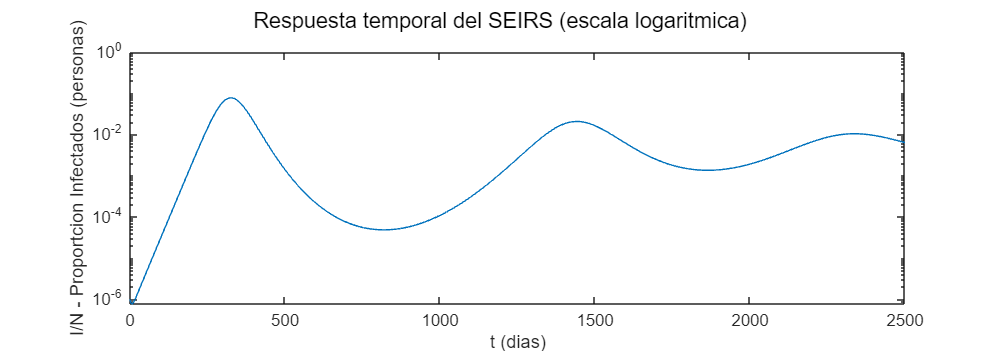

T=2500; 
B=0.0001*1000; %B
d=0.0001*1000; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_dos;
nu=0.001*10; %nu_

mdl = 'SEIRS';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
set_param(path, 'Ruido',0);

S0=1-1e-6;
E0=0;
I0=1e-6;
R0=0;
TS=1;
U=timetable(seconds(0),0);
simulacion_1_verificacion=sim("SEIRS.slx");
tiempo=simulacion_1_verificacion.tout;
infectados=simulacion_1_verificacion.I.signals.values;

h1 = figure;
subplot(1,1,1), plot(tiempo,infectados), xlabel('t (dias)'), ylabel('I/N - Proportcion Infectados (personas)')
set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
sgtitle('Respuesta temporal del SEIRS (escala logaritmica)')

### 3.2 Generacion de datos

#### 3.2.1.Generacion Con Entrada PRBS

T=20000;
B=0.0001*1000; %B
d=0.0001*1000; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_dos;
nu=0.001*10; %nu_

mdl = 'SEIRS';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;
TS=10;

time = (0:10:T)';
Rango_PRBS=[0.3 0.7];
U=timetable(seconds(time),idinput([2001, 1, 1], 'PRBS', [0, 1/10], [Rango_PRBS(1),Rango_PRBS(2)]));

dir_modelo = "SEIRS.slx";
Sim_Data_PRBS=sim(dir_modelo);
Infectados_PRBS=Sim_Data_PRBS.I.signals.values;
Entrada_PRBS=Sim_Data_PRBS.Entrada_U.signals.values;
t_Entrada_PRBS=Sim_Data_PRBS.Entrada_U.time;
t_I_PRBS=Sim_Data_PRBS.I.time;

#### 3.2.2.Grafica De Datos Generados (PRBS)

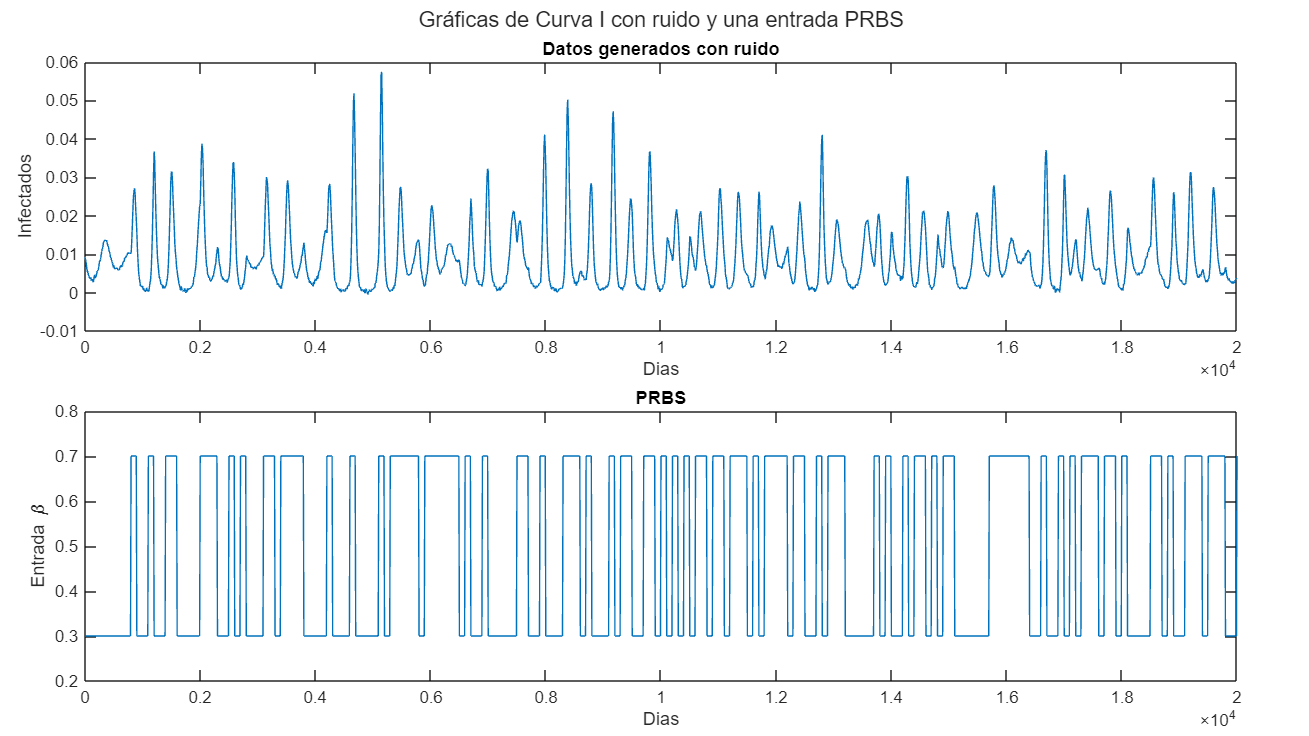

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile,plot(t_I_PRBS,Infectados_PRBS),xlabel('Dias');ylabel('Infectados');title('Datos generados con ruido');

nexttile
plot(t_Entrada_PRBS,Entrada_PRBS),ylim([0.2 0.8]);xlabel('Dias');ylabel('Entrada \beta');title('PRBS');sgtitle('Gráficas de Curva I con ruido y una entrada PRBS');

#### 3.2.3 Generacion Con Entrada Escalon

T=2000;
B=0.0001*1000; %B
d=0.0001*1000; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_dos;
nu=0.001*10; %nu_

mdl = 'SEIRS';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;
TS=10;
time = (0:10:T)';
U = timetable(seconds(time),(time>=0)*0.4+0.3);
dir_modelo = "SEIRS.slx";
Sim_Data_Escalon=sim(dir_modelo);
Infectados_Escalon=Sim_Data_Escalon.I.signals.values;
Entrada_Escalon=Sim_Data_Escalon.Entrada_U.signals.values;
t_Entrada_Escalon=Sim_Data_Escalon.Entrada_U.time;
t_I_Escalon=Sim_Data_Escalon.I.time;

#### 3.2.4.Grafica De Datos Generados (Escalon)

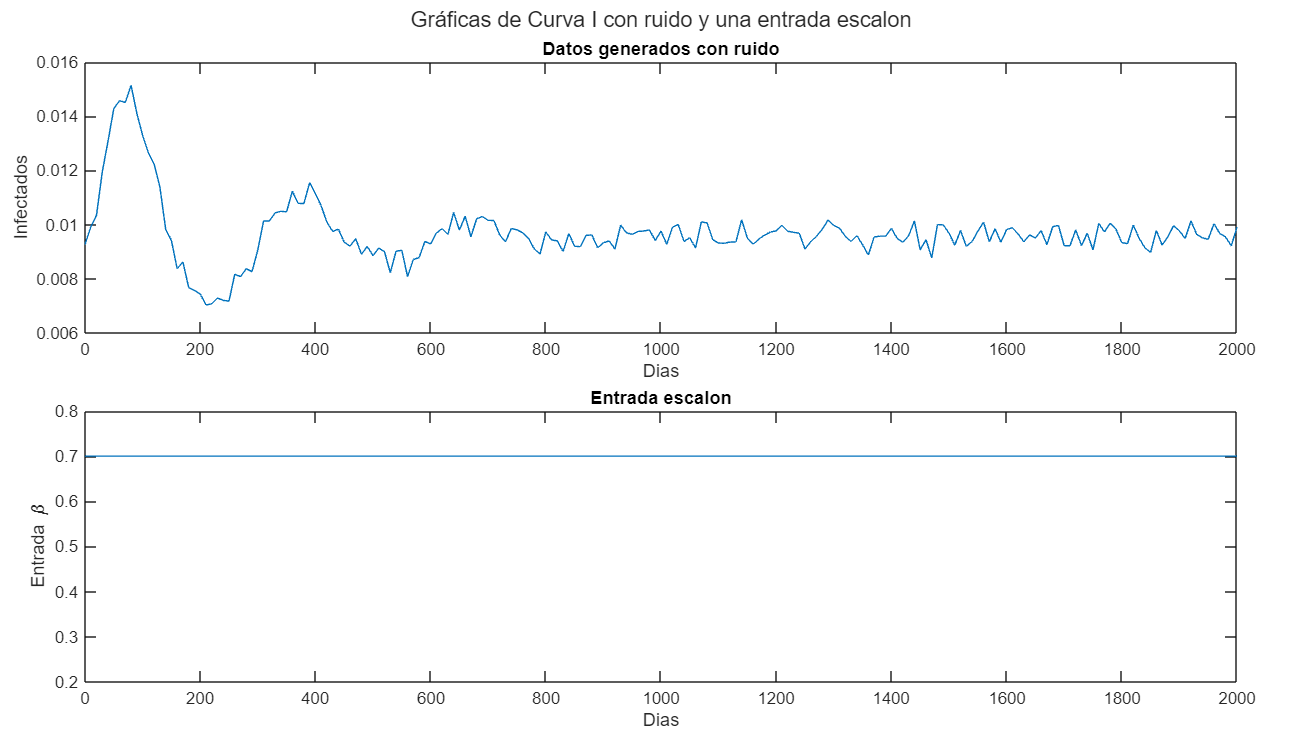

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile,plot(t_I_Escalon,Infectados_Escalon),xlabel('Dias');ylabel('Infectados');title('Datos generados con ruido');

nexttile
plot(t_Entrada_Escalon,Entrada_Escalon),ylim([0.2 0.8]);xlabel('Dias');ylabel('Entrada \beta');title('Entrada escalon');sgtitle('Gráficas de Curva I con ruido y una entrada escalon');

#### 3.2.5.Generacion Con Una Entrada senoisiodal

T=2300;
B=0.0001*1000; %B
d=0.0001*1000; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_dos;
nu=0.001*10; %nu_

mdl = 'SEIRS';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;
TS=10;

time = (0:10:T)';
U=timetable(seconds(time),-sin(time*2*pi/1000)*0.2+0.5);
dir_modelo = "SEIRS.slx";
Sim_Data_Seno=sim(dir_modelo);

Infectados_Seno=Sim_Data_Seno.I.signals.values;
Entrada_Seno=Sim_Data_Seno.Entrada_U.signals.values;
t_Entrada_Seno=Sim_Data_Seno.Entrada_U.time;
t_I_Seno=Sim_Data_Seno.I.time;


#### 3.2.6.Grafica De Datos Generados (Escalon)

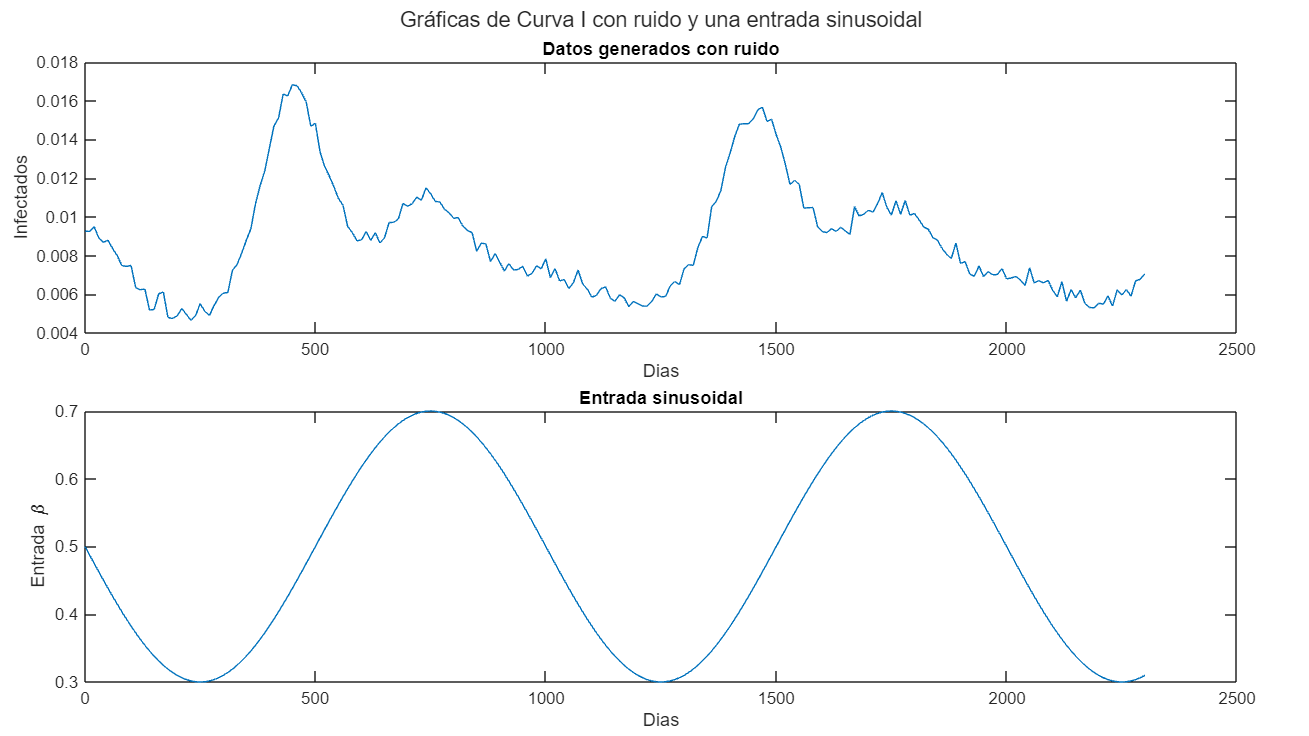

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile
plot(t_I_Seno,Infectados_Seno),xlabel('Dias');ylabel('Infectados');title('Datos generados con ruido');

nexttile
plot(t_Entrada_Seno,Entrada_Seno),xlabel('Dias');ylabel('Entrada \beta');title('Entrada sinusoidal');sgtitle('Gráficas de Curva I con ruido y una entrada sinusoidal');

### 3.3. Estimacion de parametros 

#### 3.3.1. Metodo de búsqueda exhaustiva

T=20000;
B=0.0001*1000; %B
d=0.0001*1000; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_dos;
nu=0.001*10; %nu_

mdl = 'SEIRS';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));

set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;
TS=10;
time = (0:10:T)';
Rango_PRBS=[0.3 0.7];
U=timetable(seconds(time),idinput([2001, 1, 1], 'PRBS', [0, 1/10], [Rango_PRBS(1),Rango_PRBS(2)]));


y=Infectados_PRBS;
N=length(y);
a1_min = 0.05; a1_max = 0.25;  ai_incr = 0.01; a1 = a1_min:ai_incr:a1_max; Na1 = length(a1);
a2_min = 0.05; a2_max = 0.25; a2_incr = 0.01; a2 = a2_min:a2_incr:a2_max; Na2 = length(a2);
Nsim = Na1*Na2;
V = zeros(Na1,Na2);



for i_a1=1:Na1
    
    for j_a2=1:Na2

        set_param(path, 'gamma', num2str(a1(i_a1)));
        set_param(path, 'alpha', num2str(a2(j_a2)));       
        yest = sim("SEIRS.slx").I.signals.values;
        V(i_a1,j_a2) = sum((y-yest).^2)/N; % Función de coste MSE
    end
 end
Vopt = min(V(:));
[i_a1_opt,j_a2_opt] = find(V==Vopt);
Par_opt = [a1(i_a1_opt) a2(j_a2_opt)];
t_fin = toc;
disp(['Tiempo de cómputo = ' num2str(t_fin/90) ' min'])

#### 3.3.2. Malla de resultados

figure('Units','normalized','Position',[0 0 1 0.5])
subplot(2,2,[1 3])
mesh(a2,a1,V)
xlabel('a2'), ylabel('a1'), zlabel('V = MSE')
subplot(2,2,2)
plot(a1,V(:,j_a2_opt)), xlabel('a1'), ylabel('V = MSE (a2 = a2opt)')
subplot(2,2,4)
plot(a2,V(i_a1_opt,:)), xlabel('a2'), ylabel('V = MSE, (a1 = a1opt)')

#### 3.3.3. Matlab Toolbox

#### 3.# Metaheuristico (algoritmo genetico)

B=0.0001*1000; %B
d=0.0001*1000; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_dos;
nu=0.001*10; %nu_

mdl = 'SEIRS';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;
TS=10;
T=2000;
time = (0:10:T)';
Rango_PRBS=[0.3 0.7];
U=timetable(seconds(time),idinput([201, 1, 1], 'PRBS', [0, 1/10], [Rango_PRBS(1),Rango_PRBS(2)]));

y_exp=sim("SEIRS.slx").I.signals.values;

param_bounds = [0, 1; 0, 1; 0, 1; 0, 1; 0, 1; 0, 1];


[best_params, best_fitness,mejores_parametros, mejores_fitness, mejores_residuales ] = genetic_algorithm(U, y_exp, 100, 100, param_bounds);

Generation 1: Best Fitness = 6.708658e-05
Generation 2: Best Fitness = 6.708658e-05
Generation 3: Best Fitness = 6.708658e-05
Generation 4: Best Fitness = 6.614992e-05
Generation 5: Best Fitness = 5.788365e-05
Generation 6: Best Fitness = 5.788365e-05
Generation 7: Best Fitness = 5.425917e-05
Generation 8: Best Fitness = 5.369819e-05
Generation 9: Best Fitness = 5.077017e-05
Generation 10: Best Fitness = 5.077017e-05
